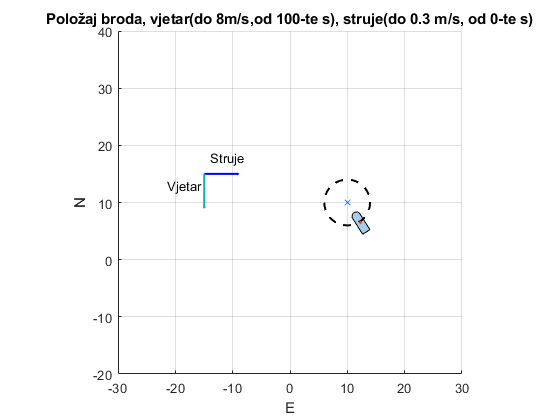


% Crtane figure broda
x=[-0.75 -0.75 -0.75*cos(deg2rad(10))...
    -0.75*cos(deg2rad(20)) -0.75*cos(deg2rad(30))...
    -0.75*cos(deg2rad(40)) -0.75*cos(deg2rad(50))...
    -0.75*cos(deg2rad(60)) -0.75*cos(deg2rad(70))...
    -0.75*cos(deg2rad(80)) 0 ...
    0.75*cos(deg2rad(80)) 0.75*cos(deg2rad(70))...
    0.75*cos(deg2rad(60)) 0.75*cos(deg2rad(50))...
    0.75*cos(deg2rad(40)) 0.75*cos(deg2rad(30))...
    0.75*cos(deg2rad(20)) 0.75*cos(deg2rad(10))...
    0.75 0.75];
y=[-2 1.25 1.25+0.75*sin(deg2rad(10))...
    1.25+0.75*sin(deg2rad(20)) 1.25+0.75*sin(deg2rad(30))...
    1.25+0.75*sin(deg2rad(40)) 1.25+0.75*sin(deg2rad(50))...
    1.25+0.75*sin(deg2rad(60)) 1.25+0.75*sin(deg2rad(70))...
    1.25+0.75*sin(deg2rad(80)) 2 ...
    1.25+0.75*sin(deg2rad(80)) 1.25+0.75*sin(deg2rad(70))...
    1.25+0.75*sin(deg2rad(60)) 1.25+0.75*sin(deg2rad(50))...
    1.25+0.75*sin(deg2rad(40)) 1.25+0.75*sin(deg2rad(30))...
    1.25+0.75*sin(deg2rad(20)) 1.25+0.75*sin(deg2rad(10))...
    1.25 -2];
b=polyshape(x,y);

Kurs = out.PSI.Data;
Brzina_u = out.U.Data;
Brzina_v = out.V.Data;
Polozaj_E = out.E.Data;
Polozaj_N = out.N.Data;
Vrijeme = out.tout;
Vjetar = out.vjetar.Data/(max(out.vjetar.Data))*6+0.01;
Struja = out.struja.Data/(max(out.struja.Data))*6+0.01;

F=struct('cdata',zeros(560,420,3,'uint8'),'colormap',[]);
j=1;

for i=1:round(length(Vrijeme)/400):length(Vrijeme)
figure(4)
b1=translate(b,[Polozaj_E(i) Polozaj_N(i)]);
b2=rotate(b1,-Kurs(i),[Polozaj_E(i) Polozaj_N(i)]);
plot(b2)
hold on
pvec(-15,15,Struja(i),0,'blue'," ",'-',1.5);
hold on
pvec(-15,15,Vjetar(i),-90,[0 0.7 0.7]," ",'-',1.5);
hold on
rectangle('Position',[E_c - r_o, N_c - r_o, r_o*2, r_o*2],'Curvature',[1,1],'LineWidth',1.5,'LineStyle',"--");
hold on
plot(10,10,'x')
hold on
text(-21.5,13,"Vjetar")
text(-14,18,"Struje")
grid on
title("Položaj broda, vjetar(do 8m/s,od 100-te s), struje(do 0.3 m/s, od 0-te s)");
xlabel("E");
ylabel("N");
hold on
plot(Polozaj_E(i),Polozaj_N(i),'*','MarkerSize',2)
axis([-30 30 -20 40])
F(j)=getframe(gcf);
j=j+1;
hold off
end


%Stvaranje videa iz sličica nakon svake iteracije
writerObj = VideoWriter('Animacija.avi');
writerObj.FrameRate = 8;
open(writerObj);
for k=1:length(F)
    frame = F(k);    
    writeVideo(writerObj, frame);
end
close(writerObj);